# ROZWIĄZAYWANIE UKŁADÓW RÓWNAŃ LINIOWYCH

## Metoda rozkładu LU

Aby zobrazować zaletę metody LU pod względem rozwiązywania powtarzalnych zadań różniących się miedzy sobą tylko wektorami ***b***, poniżej przygotowano kod rozwiązujący przykładowy problem o rosnącym rozmiarze - jest on generowany losowo. 

Wykreślana jest podobnie jak poprzednio estymata złożoności czasowej w postaci czasu wykonania obliczeń. Dla porównania metody LU z eliminacją Gaussa, która za każdym razem musi przekształcać macierz ***A*** i wektor ***b***, kolorem niebieskim pokazano ten sam parametr dla eliminacji Gaussa.

- Linią ciągłą czerwoną zaznaczono estymatę złożoności **bez nakładu na sam rozkład **(samo rozwiązanie) - odpowiada to sytuacji kiedy macierz ***A*** jest powtarzalna, a zmienia się tylko wektor ***b***

- Linią czerwoną przerywaną zaznaczono estymatę złożoności uwzględniając rozkład LU

- Linią ciągłą niebieską zaznaczono estymatę złożoności dla metody Gaussa.

**UWAGA! ** Metoda LU uwzględniając rozkład i metoda Gaussa mają tę samą klasę złożoności $O\left(n^3 \right)$- jak widzisz na rysunku klasa złożoności to nie sama złożoność. Czas wykonania obliczeń nawet przy tej samej klasie złożoności może się znacznie różnić. Bo choć obie krzywe można ograniczyć wielomianem stopnia 3 to są to różne wielomiany i różne stałe C. Jak widzisz ma to istoty wpływ na praktyczne właściwości metody.

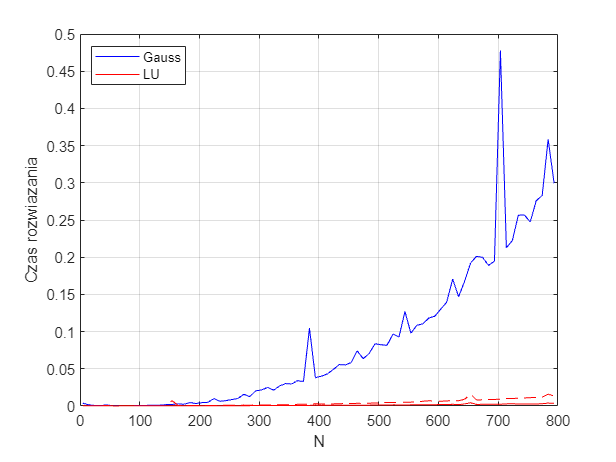

%Czyszczenie
clear all;
close all;
clc;

% Poniżej prowadzamy maksymalna ilość równań i krok z jakim ma być
% zwiększana ilość równań zaczynając od 4
Nmax=800;
step=10;

zlozonoscGauss=[];zlozonoscLU=[];zlozonoscLUFull=[];
N=[];maxNumCompThreads(1);

%Generujemy losowy układ równań o rozwiązaniu będącym wektorem samych
%jedynek
h = waitbar(0,'Rozwiazywanie...');
for i=[4:step:Nmax]
    A=rand(i);
    b=sum(A,2);
    [timeAll, timeSimple, error]=solveUsingGaussElimination(A,b);
    zlozonoscGauss=[zlozonoscGauss timeAll];N=[N i];warning('off');
    [timeAll, timeSimple, error]=solveUsingLUFactorization(A,b);
    zlozonoscLU=[zlozonoscLU timeSimple];zlozonoscLUFull=[zlozonoscLUFull timeAll];
    
    %Rysowanie
    
    tiledlayout(1,1)
    nexttile
    plot(N,zlozonoscGauss,'b',N,zlozonoscLU,'r',N,zlozonoscLUFull,'r--');xlabel("N");ylabel("Czas rozwiazania");grid on; 
    legend("Gauss", "LU",'Location','northwest');
    waitbar(i / Nmax);
end

close(h);warning('on');
 

## Wykorzystywane funkcje

function [timeAll, timeSimple, error]=solveUsingLUFactorization(A,b)

%Startujemy licznik czasu
time1 = tic;

%Rozkład LU
%[L,U,P]=lu(A);
[L,U]=lu(A);

%Startujemy licznik tylko obliczenia
time2 = tic;

%Rozwiązanie metodą LU w dwóch krokach zapisane w jednej linijce żeby
%prawidłowo mierzyć złożoność
x = U\(L\b);
% Rozpisane na dwie linijki byłoby y = L\(P*b); x = U\y;

%Zakończenie liczenia czasu
time2end = toc(time2);
time1end = toc(time1);

%Obliczenie błędów zakładając, że rozwiązaniem jest wektor jedynek
error=(norm(x-ones(numel(b),1)))/norm(ones(numel(b),1));

%Inne wartosci wyjściowe
timeAll=time1end;
timeSimple=time2end;
end

function [timeAll, timeSimple, error]=solveUsingGaussElimination(A,b)

%Startujemy licznik czasu
time1 = tic;

%Wywołanie algorytmu Gaussa
x = solveGauss(A,b);

%Zakończenie liczenia czasu
time1end = toc(time1);

%Obliczenie błędów zakłądając, ze rozwiazaniem jest wektor jedynek
error=(norm(x-ones(numel(b),1)))/norm(ones(numel(b),1));

%Inne wartosci wyjściowe
timeAll=time1end;
timeSimple=0;
end

function x = solveGauss(A,b)

%Produkwoanie macierzy trójkątnej
s = length(A);
for j = 1:(s-1)
    for i = s:-1:j+1
        %Przeprowadzamy operacje elementarne
        m = A(i,j)/A(j,j);           % Znajdowanie wspólnego mianownika
        A(i,:) = A(i,:) - m*A(j,:);  % Odejmowanie wielokrotności wiersza
        b(i) = b(i) - m*b(j);        % To samo musimy zrobić na wektorze b
    end
end 

% Rozwiązanie - eliminacja prosta
x = zeros(s,1);
x(s) = b(s)/A(s,s);               
for i = s-1:-1:1                    
    sum = 0;
    for j = s:-1:i+1                
        sum = sum + A(i,j)*x(j);    
    end 
    x(i) = (b(i)- sum)/A(i,i);
end 
end